# **Video Processing: Laboratory 1:**

Adrià Garcia Coscolla: u232256

Ernest Fosch Muntané: u196572

### **Task 1.a:**

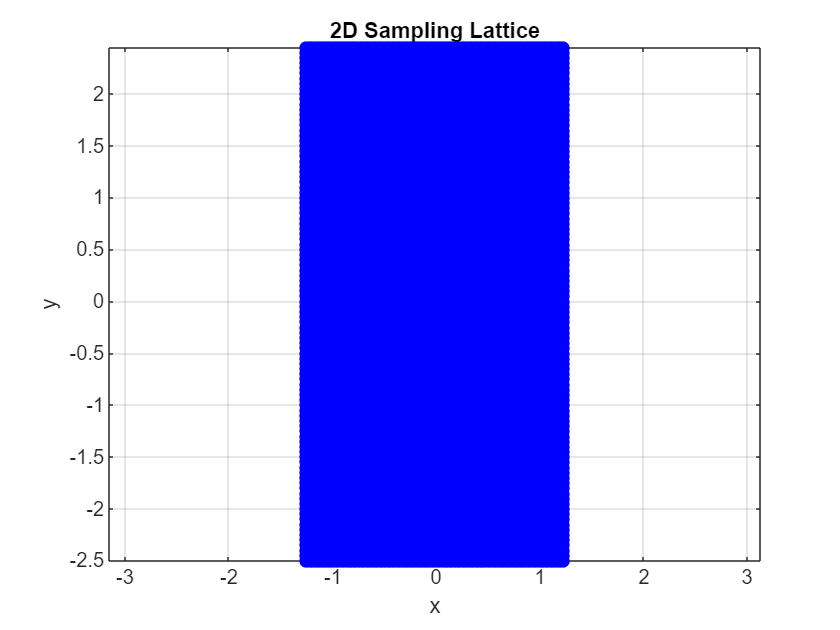

a=6;
b=2;
N=100; %We will have NxN samples if N is even or (N-1)x(N-1) if is odd.

[m,n]= meshgrid(-floor(N/2):floor(N/2)-1); %integer grid

psi= @(x,y)cos(2*pi*a*x) .* cos(2*pi*b*y) + ...
0.7*sin(pi*a*b*(x+y)) + ...
0.5*cos(pi*(a + 0.5*a*b)*x - pi*b*y); 

%sampling lattice:
V=[1/40,0;0,1/20];
% sampling grid, because V is diagonal:
x = V(1,1)*m;
y = V(2,2)*n;

psi_s = psi(x, y); %sampling of the function: psi_s = psi(Vn)

%2D plot of the sample lattice grid.
figure;
plot(x,y, '.', 'MarkerSize', 20,'Color', 'b');
title('2D Sampling Lattice');
xlabel('x'); ylabel('y');
axis equal tight;
grid on;

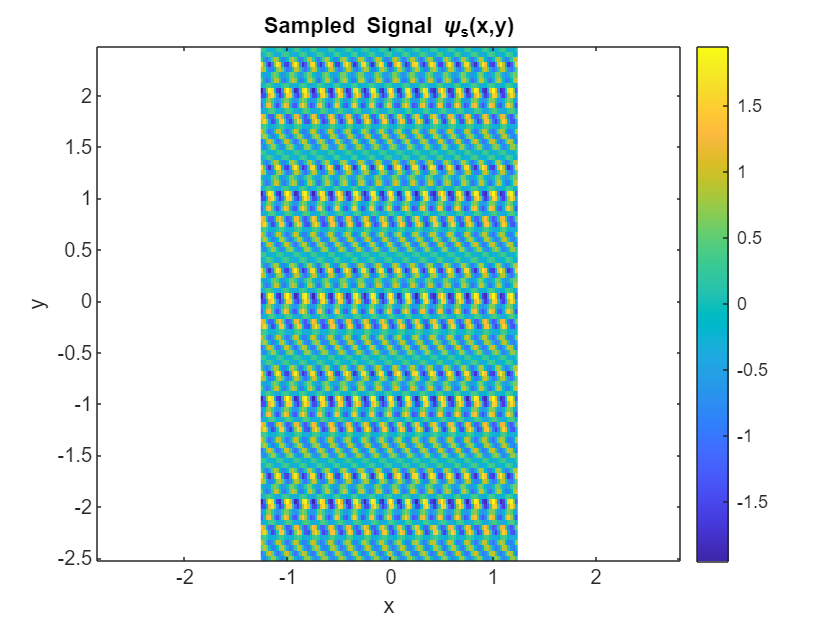


%2D plot of the sampled signal (psi_s)
figure;
imagesc(x(1,:), y(:,1), psi_s);
title('Sampled Signal \psi_s(x,y)');
xlabel('x'); ylabel('y');
colorbar;
axis xy; %y pointing up
axis equal tight;

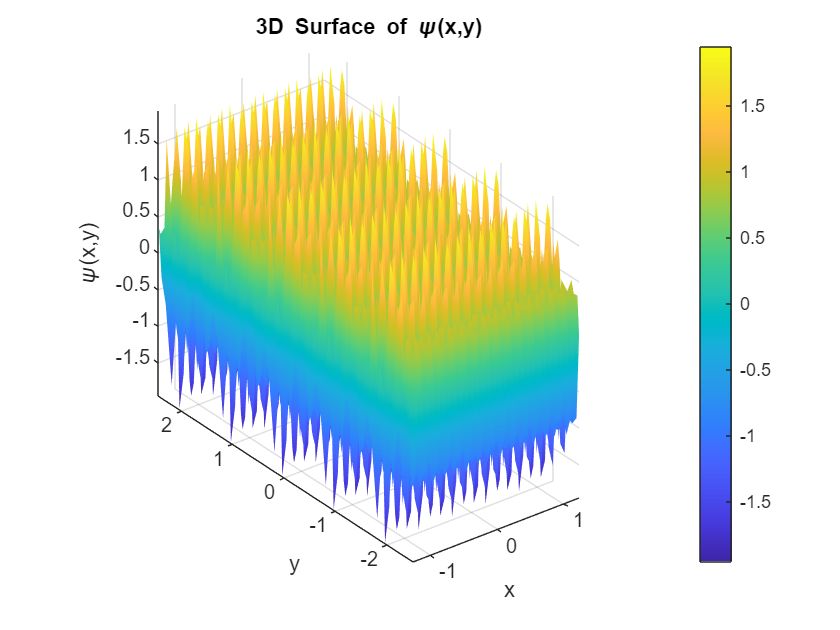


%3D plot of the sampled signal (psi_s)
figure;
surf(x, y, psi_s); % 3D surface
shading interp; % smooth shading
colorbar; % show color scale
axis equal;
xlabel('x'); ylabel('y'); zlabel('\psi(x,y)');
title('3D Surface of \psi(x,y)');

%Another way to create the sampling lattice grid:
%m = -floor(N/2)*V(1,1):V(1,1):(floor(N/2)-1)*V(1,1);
%n = -floor(N/2)*V(2,2):V(2,2):(floor(N/2)-1)*V(2,2);
%   [x,y]= meshgrid(m, n); %integer grid

**Task 1.b:**

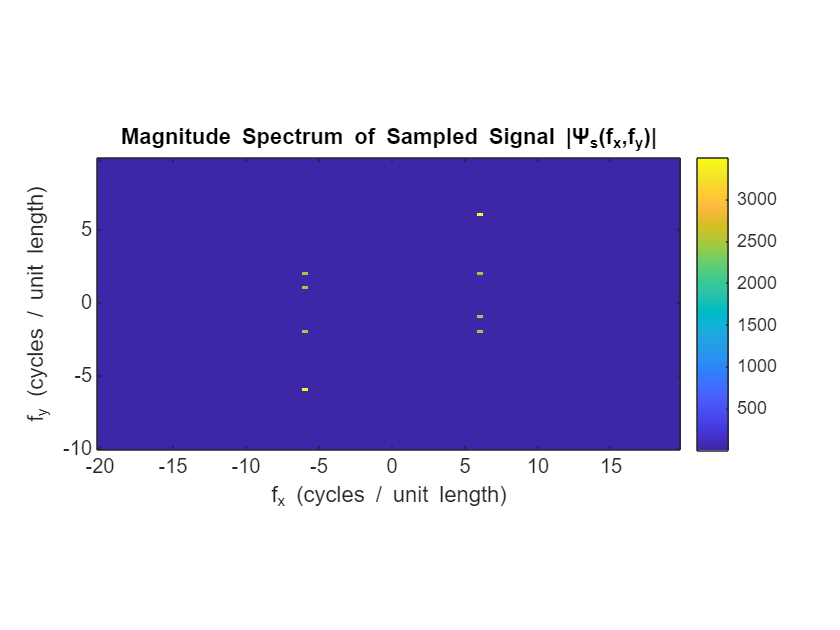

% 2D FFT of the sampled signal:
Psi = fftshift(fft2(psi_s)); % to center the frequency.

% Magnitude spectrum
Psi_mag = abs(Psi);

% log scale for better visibility
% Psi_log = log(1 + Psi_mag);

Nx = size(psi_s, 2);   % # columns
Ny = size(psi_s, 1);   % # rows

dx = V(1,1);   % 1/40: the increment on the x axis
dy = V(2,2);   % 1/20: the increment on the y axis

% x and y axes in frequency:
fx = (-Nx/2:Nx/2-1)/(Nx*dx);
fy = (-Ny/2:Ny/2-1)/(Ny*dy);

figure;
imagesc(fx, fy, Psi_mag);
axis xy;
axis equal tight;
colorbar;

xlabel('f_x (cycles / unit length)');
ylabel('f_y (cycles / unit length)');
title('Magnitude Spectrum of Sampled Signal |\Psi_s(f_x,f_y)|');

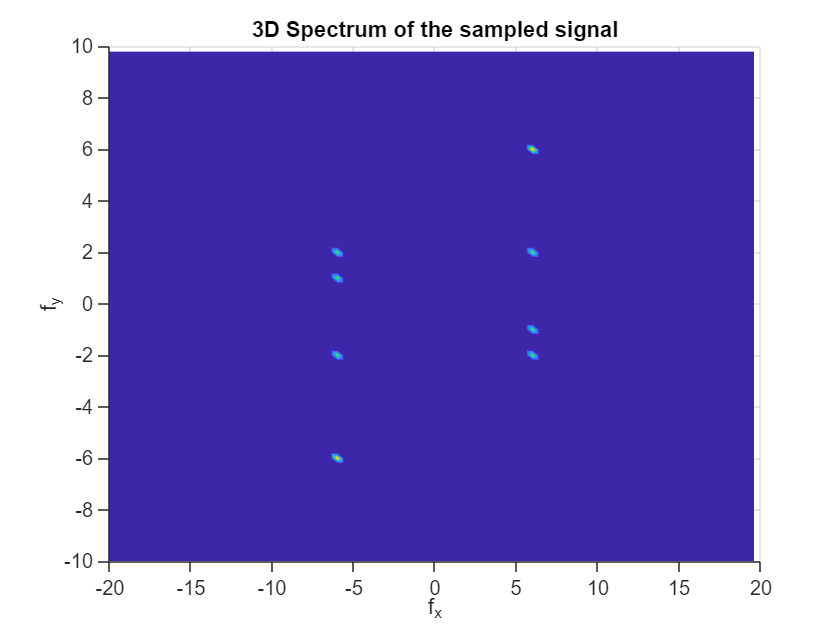


figure;
surf(fx, fy, Psi_mag);
shading interp;
xlabel('f_x'); ylabel('f_y'); zlabel('|F(f_x,f_y)|');
title('3D Spectrum of the sampled signal');

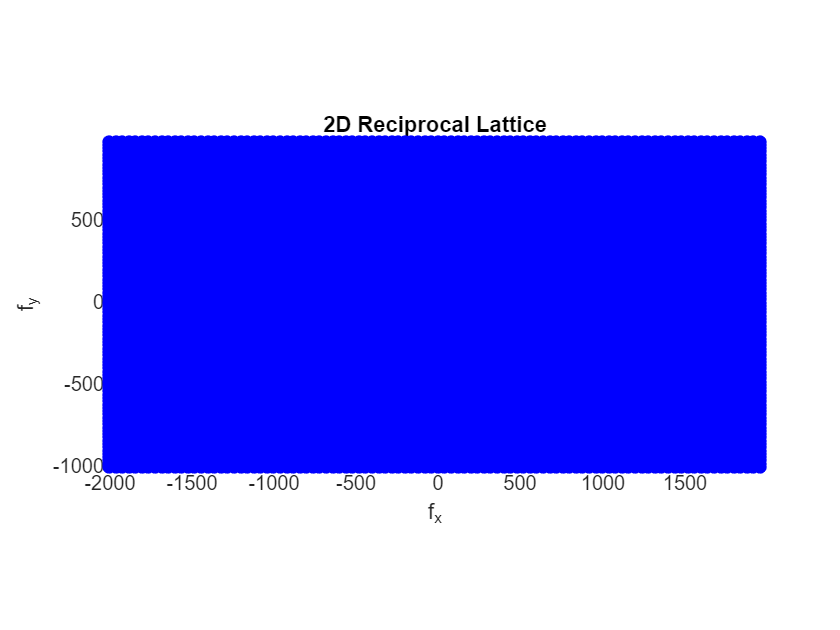

%reciprocal latice
U = inv(V');
m = -N/2*U(1,1):U(1,1):(N/2-1)*U(1,1);
n = -N/2*U(2,2):U(2,2):(N/2-1)*U(2,2);
[f_x,f_y]= meshgrid(m,n);

%2D plot of the reciprocal lattice grid.
figure;
plot(f_x,f_y,'.', 'MarkerSize', 20,'Color', 'b')
title('2D Reciprocal Lattice');
xlabel('f_x'); ylabel('f_y');
axis equal tight;
grid on;

### **Task 2.a:**

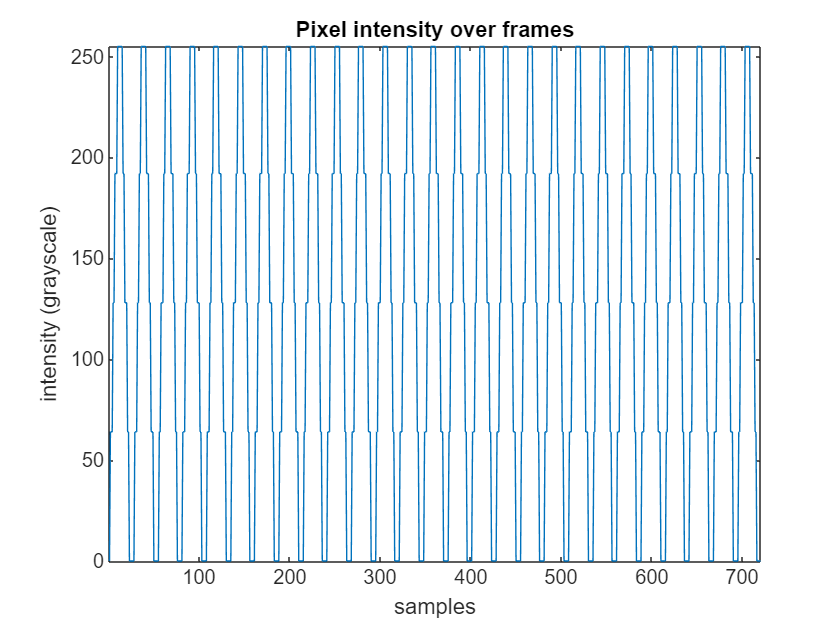

path = "\task2_orig120fps.avi";
vid = VideoReader(path);

c = 20;
d = 30;

%Coords of the pixel:
x = 5*c; 
y = 5*d;

n_frames = vid.NumFrames; %# of frames = diff values of the pixel

pixel_values = zeros(1,n_frames); %array to store the grayscale values of the pixel.
i = 1;
while hasFrame(vid)
    frame = readFrame(vid,'native');
    pixel_values(i) = double(frame.cdata(y,x)); % y: eix vertical (files), x:eix horitzontal (columnes)
    i = i+1;
end

figure;
plot(pixel_values)
xlabel('samples'); ylabel('intensity (grayscale)');
title('Pixel intensity over frames');
axis tight;

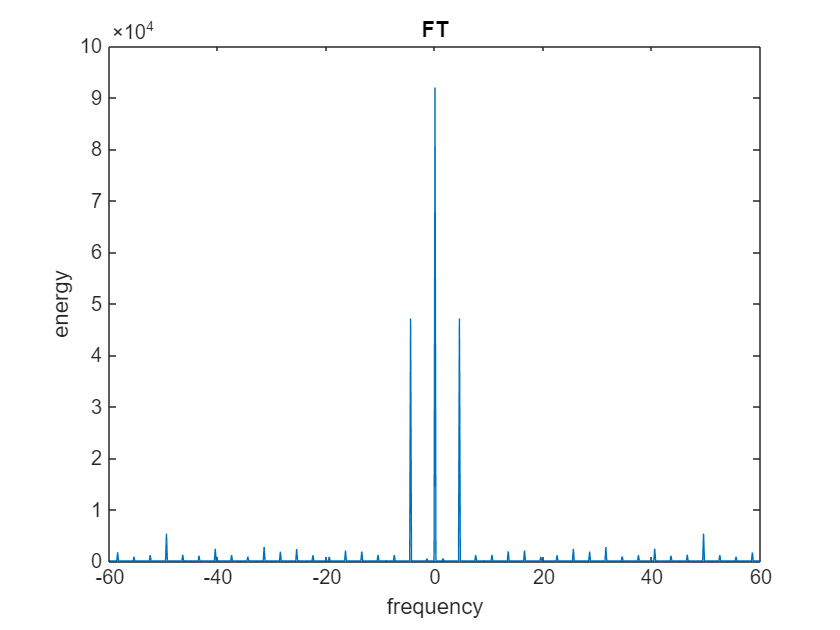


F_pixel = fftshift(fft(pixel_values));
% Magnitude spectrum
F_mag = abs(F_pixel);

fr = vid.FrameRate;
f = (-n_frames/2:n_frames/2-1)*(fr/n_frames);

figure;
plot(f, F_mag)
xlabel('frequency'); ylabel('energy');
title('FT');


clear vid;